## Performance Evaluation

- Download or use any image that is larger than 640×640 and use your code to rotate the image by 90 degrees. Use the inbuilt functions (e.g., maketform and imtransform in MATLAB Image Processing Toolbox) to perform the rotation of the same image. Comment on the difference in speed between the two approaches.

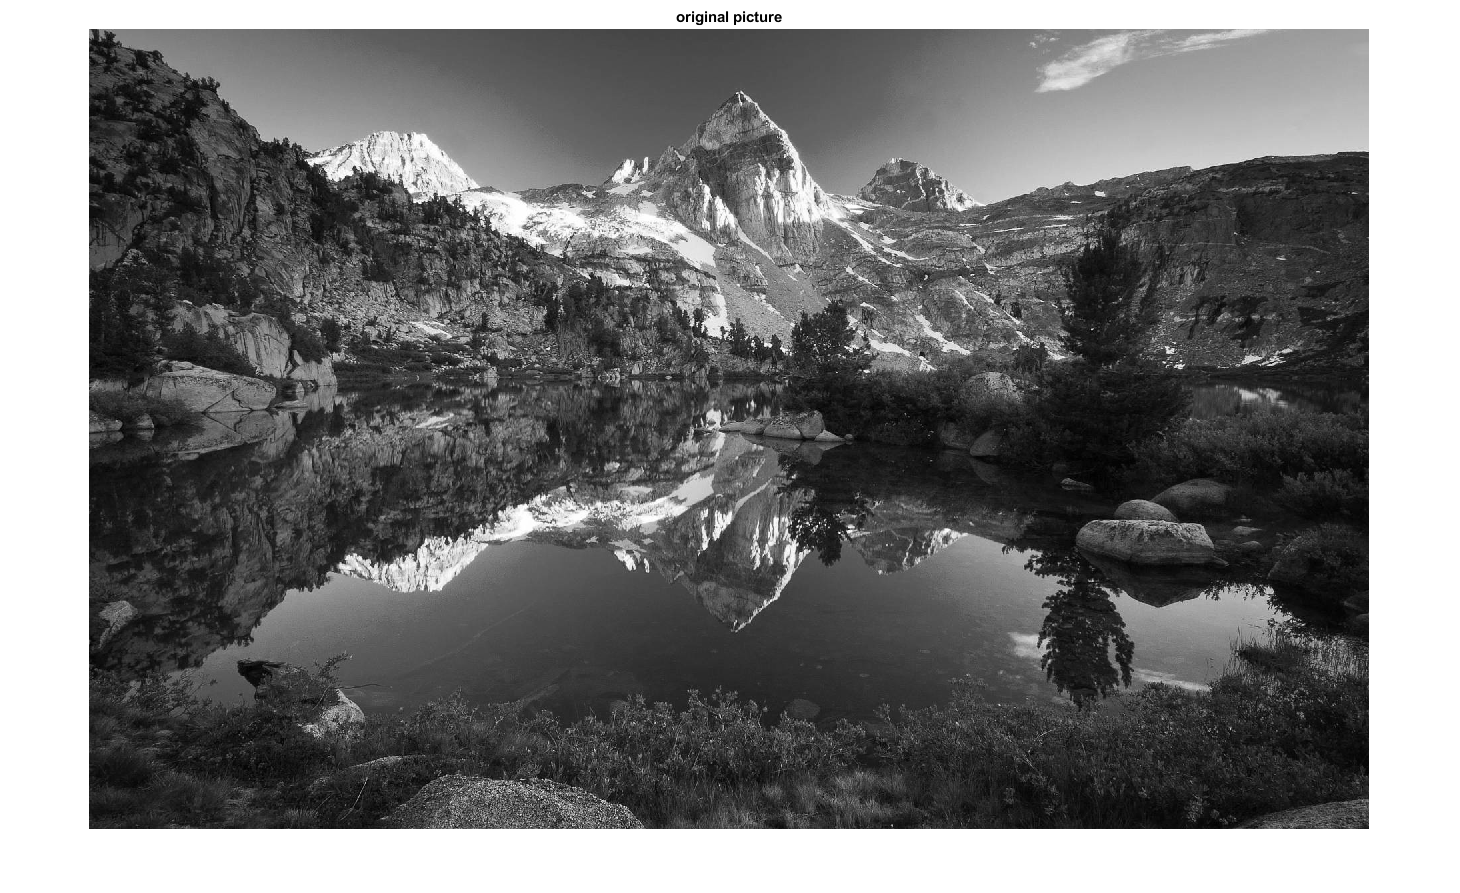

imc = imread('scenery.jpg');% Read the image
img = rgb2gray(imc); % Convert to grayscale
figure
imshow(img) % View image
title("original picture")

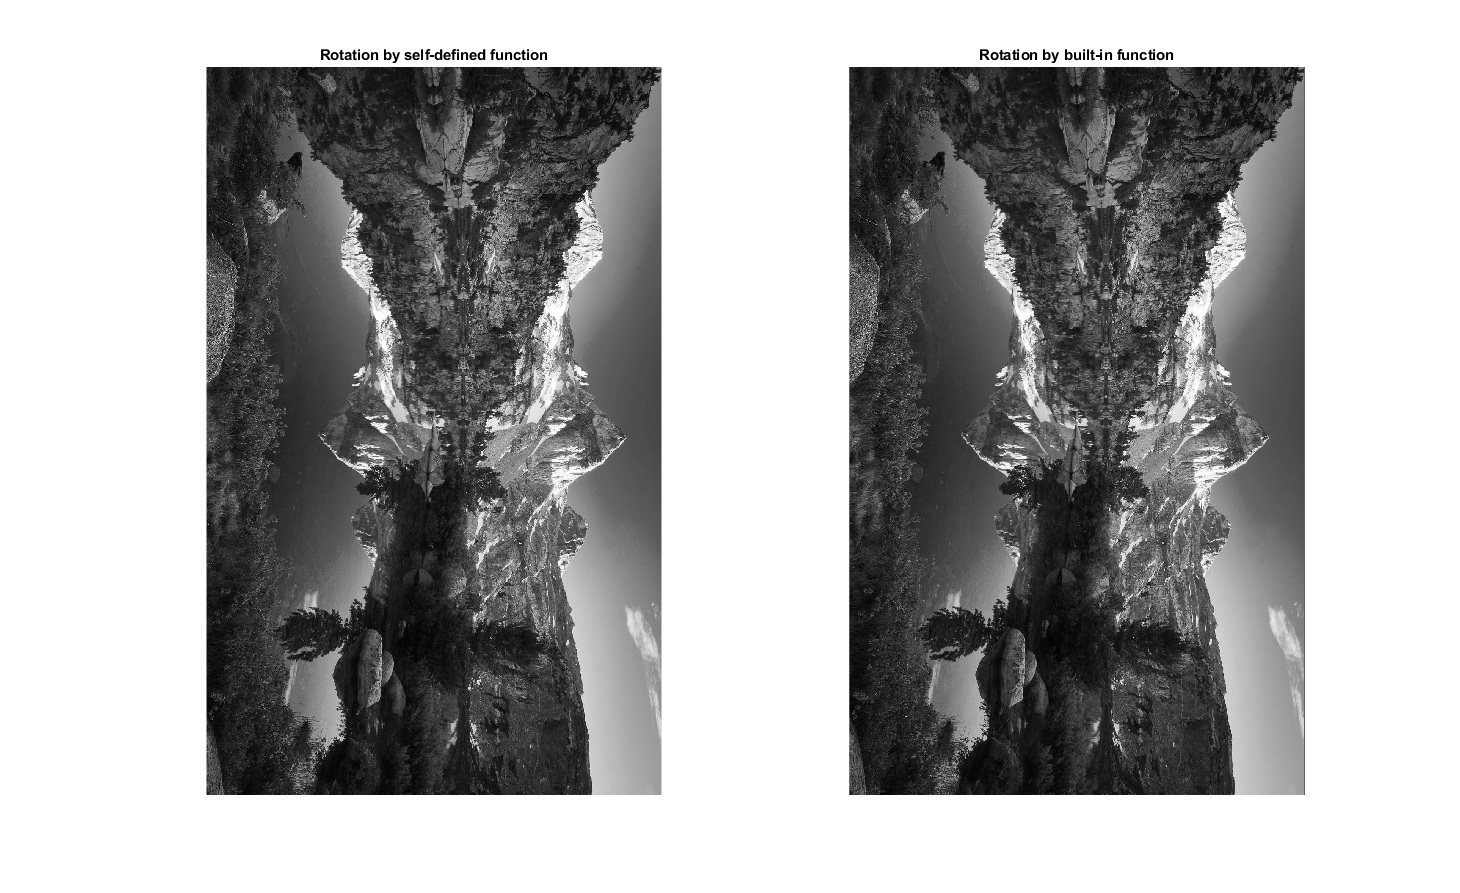


% Rotation 
theta = deg2rad(90);
R1 = [cos(theta)  sin(theta) 0; ...
     -sin(theta) cos(theta) 0; ...
     0           0          1];
R2 = maketform('affine', R1);

% handle to function
f1 = @()transform(img, R1); 
f2 = @()imtransform(img, R2);

% Clock the runing time
% Run 3 times and calculte the average time
aver1 = 0;
aver2 = 0;
for i = 1:3
    t1 = timeit(f1);
    aver1 = aver1 + t1/3;
    t2 = timeit(f2);
    aver2 = aver2 + t2/3;
end

subplot(1,2,1)
imshow(transform(img,R1), [])
title("Rotation by self-defined function")
subplot(1,2,2)
imshow(imtransform(img,R2))
title("Rotation by built-in function")

% show time
[m, n] = size(img);
sprintf("Running Time of an image of size %d x %d", m, n)

ans = "Running Time of an image of size 1200 x 1920"

sprintf("Self-defined function: %f s", aver1)

ans = "Self-defined function: 0.838708 s"

sprintf("Built-in function: %f s", aver2)

ans = "Built-in function: 0.741855 s"

#### Comment

From the result, we can tell that the self-defined function is slower than the built-in function, but not much, only 0.1s for an image with size 1200x1920(of course, it depends on the machine performance). 

The major reason is definately the double for loop. We can use vectorize technique to improve the performance.

2. Comment on the shape of the histogram resulting from the histogram equalization process. Is it a perfectly uniform histogram? If not, comment on why it is not uniform.

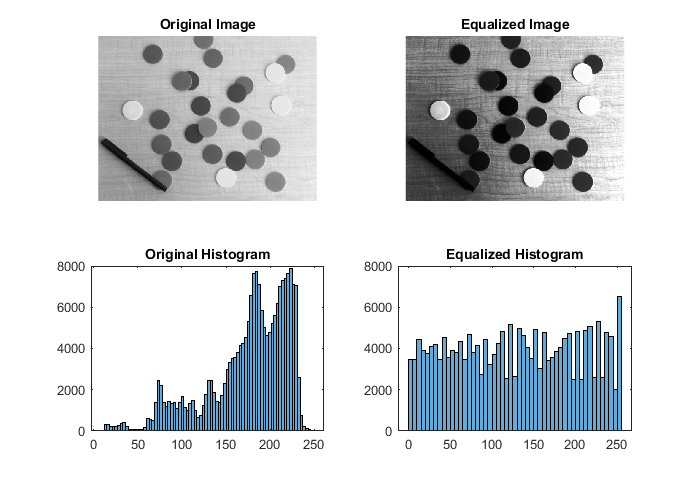

The equalized histogram is not perfectly flat. The reasons are that:

-  the histogram is discrete, which is just an approximation to a PDF

- there is no new allowed intensity levels are created during the process. the round operation in the process will converge the intensities in a small range in to an integer.